# Homework 6: Introduction to first order differential equations

## Part I

**A. Plot the vector fields + plot a time series graph for each ODE. **

% Equation 1

dt = .3

dt = 0.3000

[X,Y] = meshgrid(0:dt:6,-3:dt:3);

% define vector x and y components (U and V, respectively)
U = ones(size(X))*dt; % horizontal component (time)
V = (2*Y.^2-8).*dt; % vertical component (change in state; given by f(x)*dt

figure
quiver(X,Y,U,V,2)
xlabel('Time (s)')
ylabel('x')

% plot the ODE solutions from different initial conditions
hold on
IntMyODE_eq1(1,5)
IntMyODE_eq1(0, 5)
IntMyODE_eq1(-1, 5)
IntMyODE_eq1(-2.5, 5)
IntMyODE_eq1(3, 5)

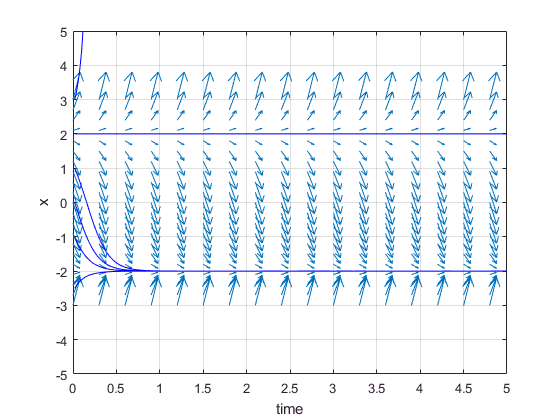

IntMyODE_eq1(2, 5)

% Equation 2
dt = .3

dt = 0.3000

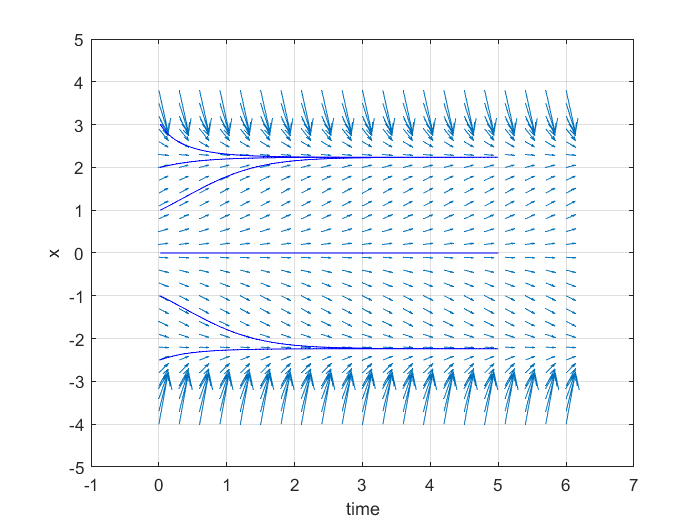

[X,Y] = meshgrid(0:dt:6,-4:dt:4);

% define vector x and y components (U and V, respectively)
U = ones(size(X))*dt; % horizontal component (time)
V = (Y-((Y.^3)/5)).*dt; % vertical component (change in state; given by f(x)*dt

figure
quiver(X,Y,U,V,3)
xlabel('Time (s)')
ylabel('x')

% plot the ODE solutions from different initial conditions
hold on
IntMyODE_eq2(1,5)
IntMyODE_eq2(0, 5)
IntMyODE_eq2(-1, 5)
IntMyODE_eq2(-2.5, 5)
IntMyODE_eq2(3, 5)
IntMyODE_eq2(2, 5)

% Equation 3
dt = 0.5

dt = 0.5000

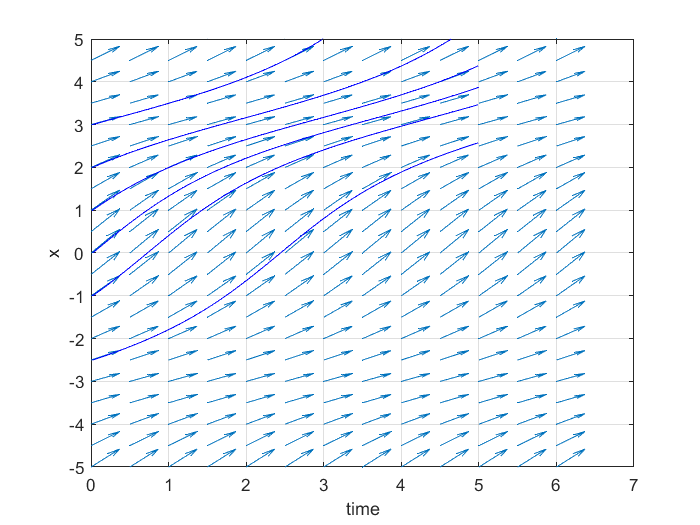

[X,Y] = meshgrid(0:dt:6,-5:dt:5);

% define vector x and y components (U and V, respectively)
U = ones(size(X))*dt; % horizontal component (time)
V = (1 + ((1/2)*cos(Y))).*dt; % vertical component (change in state; given by f(x)*dt

figure
quiver(X,Y,U,V,1)
xlabel('Time (s)')
ylabel('x')

% plot the ODE solutions from different initial conditions
hold on
IntMyODE_eq3(1,5)
IntMyODE_eq3(0, 5)
IntMyODE_eq3(-1, 5)
IntMyODE_eq3(-2.5, 5)
IntMyODE_eq3(3, 5)
IntMyODE_eq3(2, 5)

% Equation 4
dt = .3

dt = 0.3000

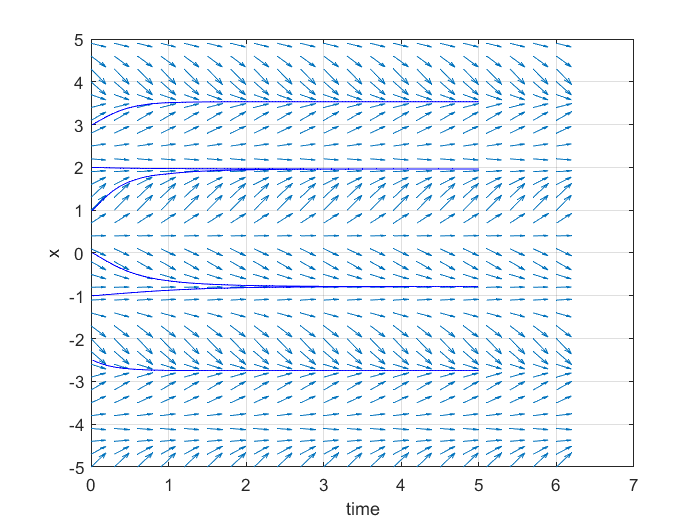

[X,Y] = meshgrid(0:dt:6,-5:dt:5);

% define vector x and y components (U and V, respectively)
U = ones(size(X))*dt; % horizontal component (time)
V = (sin(Y)-cos(3*Y)).*dt; % vertical component (change in state; given by f(x)*dt

figure
quiver(X,Y,U,V,1)
xlabel('Time (s)')
ylabel('x')

% plot the ODE solutions from different initial conditions
hold on
IntMyODE_eq4(1,5)
IntMyODE_eq4(0,5)
IntMyODE_eq4(-1,5)
IntMyODE_eq4(-2.5,5)
IntMyODE_eq4(3,5)
IntMyODE_eq4(2,5)

% Equation 5
dt = .3

dt = 0.3000

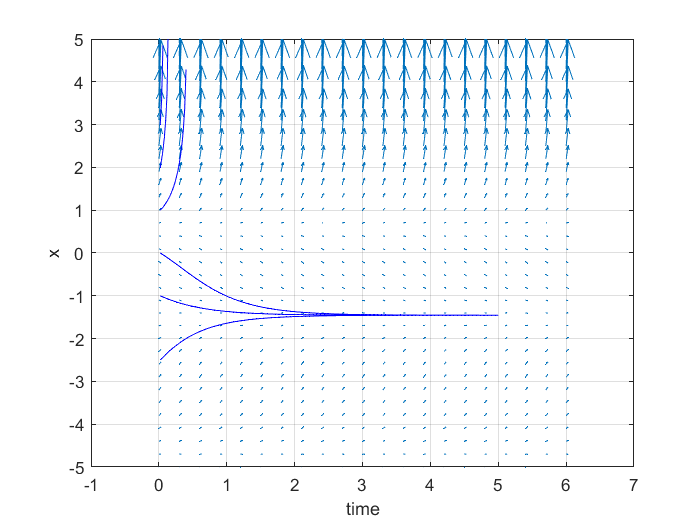

[X,Y] = meshgrid(0:dt:6,-5:dt:5);

% define vector x and y components (U and V, respectively)
U = ones(size(X))*dt; % horizontal component (time)
V = (exp(Y)-(2*cos(Y))).*dt; % vertical component (change in state; given by f(x)*dt

figure
quiver(X,Y,U,V,10)
xlabel('Time (s)')
ylabel('x')

% plot the ODE solutions from different initial conditions
hold on
IntMyODE_eq5(1,5)
IntMyODE_eq5(0, 5)
IntMyODE_eq5(-1, 5)
IntMyODE_eq5(-2.5, 5)
IntMyODE_eq5(3, 5)
IntMyODE_eq5(2, 5)

**C. Use the 'solve' function to find the fixed points for each ODE. **

% Equation 1
syms f(x)
f(x)= 2*x^2-8;

figure
fplot(f(x))
hold

Current plot held


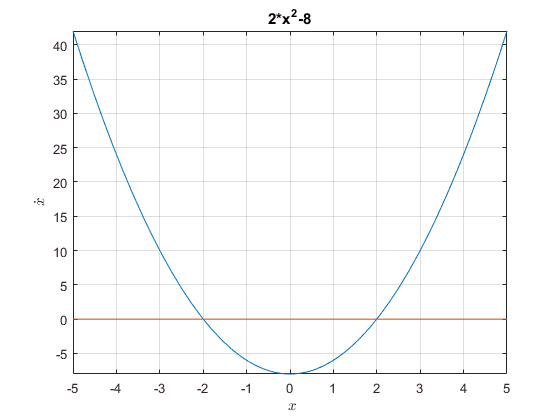

fplot(0) % add reference line for x dot = 0
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
title('2*x^2-8')


% find fixed point values
solve(f(x)==0)

$$ans = \left(\begin{array}{c} -2\\ 2 \end{array}\right)$$

% Equation 2
syms f(x)
f(x)= x-(x^3)/5;

figure
fplot(f(x),[-3, 3])
hold

Current plot held


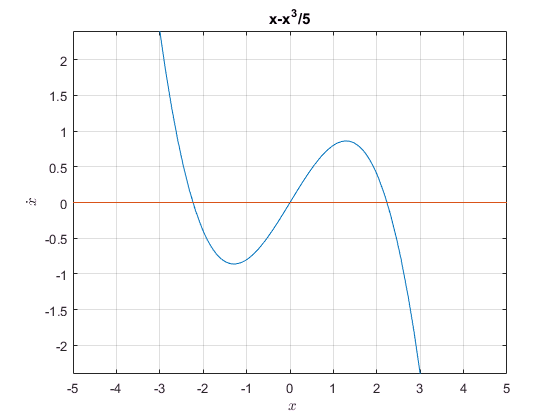

fplot(0) % add reference line for x dot = 0
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
title('x-x^3/5')


% find fixed point values
solve(f(x)==0)

$$ans = \left(\begin{array}{c} 0\\ \sqrt{5}\\ -\sqrt{5} \end{array}\right)$$

% Equation 3
syms f(x)
f(x)= 1+0.5*cos(x);

figure
fplot(f(x))
hold

Current plot held


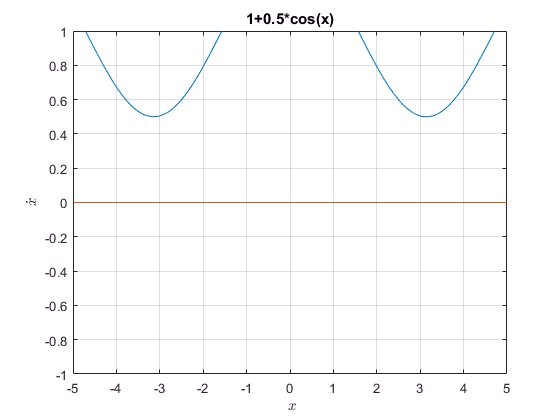

fplot(0) % add reference line for x dot = 0
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
title('1+0.5*cos(x)')


%find fixed point values
solve(f(x)==0)

$$ans = \left(\begin{array}{c} \pi +\mathrm{acos}\left(2\right)\\ \pi -\mathrm{acos}\left(2\right) \end{array}\right)$$

% Equation 4
syms f(x)
f(x)= sin(x)-cos(3*x);

figure
fplot(f(x))
hold

Current plot held


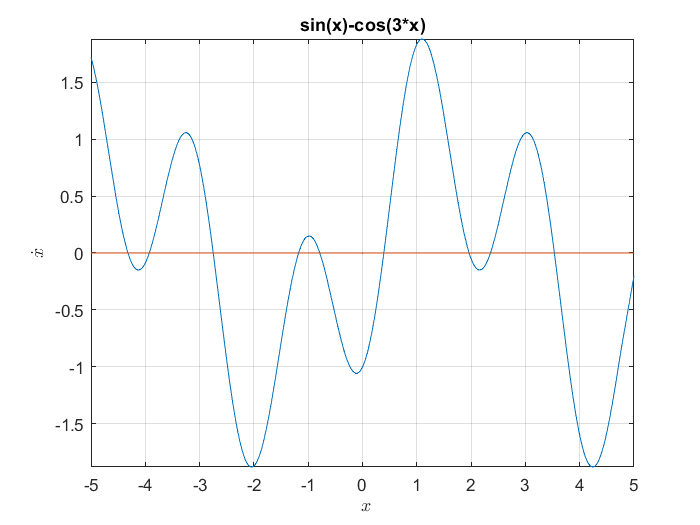

fplot(0) % add reference line for x dot = 0
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
title('sin(x)-cos(3*x)')


% find fixed point values
solve(f(x)==0)

$$ans = \left(\begin{array}{c} -\frac{\pi }{4}\\ \frac{\pi }{8} \end{array}\right)$$


% probe other fixed points that were not identified by the solve command
% using vpasolve (help vpasolve) - for example around a value -2.5
fp = vpasolve(f(x),x,-2.5)

$$fp = -2.7488935718910690836548129603696$$


% probe other fixed points around a value -1
fp = vpasolve(f(x),x,-1)

$$fp = -1.1780972450961724644234912687298$$

% Equation 5
syms f(x)
f(x)= exp(1)^x-2*cos(x);

figure
fplot(f(x),[-10,1.5])
hold

Current plot held


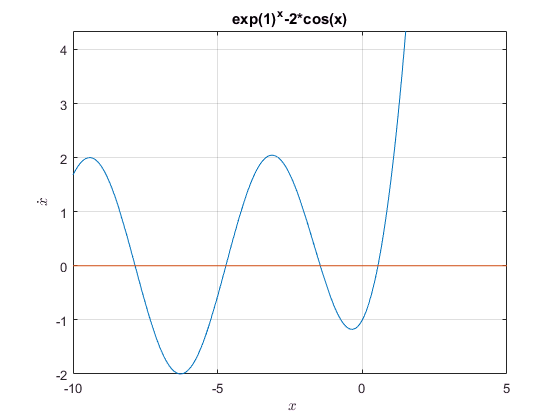

fplot(0) % add reference line for x dot = 0
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
title('exp(1)^x-2*cos(x)')

**D. Use the 'diff' function  to determine the stability of the fixed points for each ODE. **

% Equation 1
syms f(x)
f(x) = 2*x^2-8

$$f(x) = 2\,x^{2}-8$$


figure
fplot(f(x))
hold

Current plot held


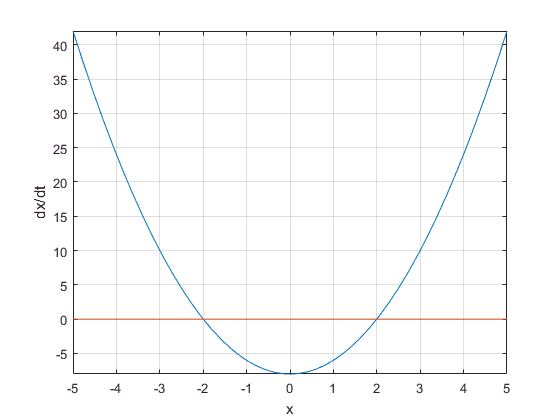

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on


% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num =     -8
     8



% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


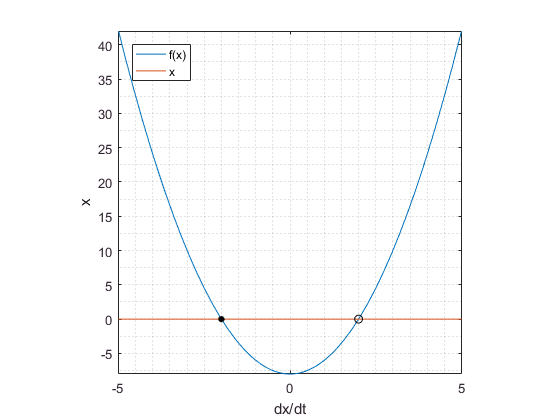

fplot(0)

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 2
syms f(x)
f(x)= x-(x^3)/5;

figure
fplot(f(x))
hold

Current plot held


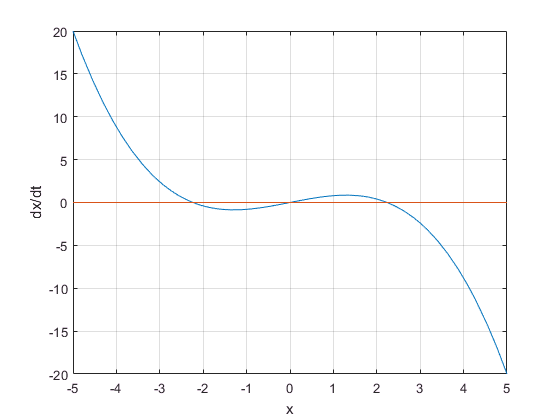

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on


% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num =      1
    -2
    -2



% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


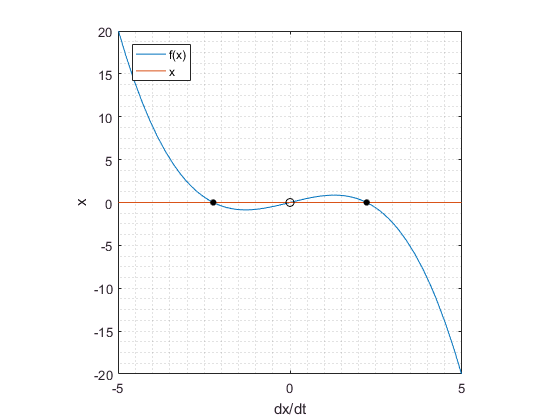

fplot(0)

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 3
syms f(x)
f(x)= 1+0.5*cos(x);

figure
fplot(f(x))
hold

Current plot held


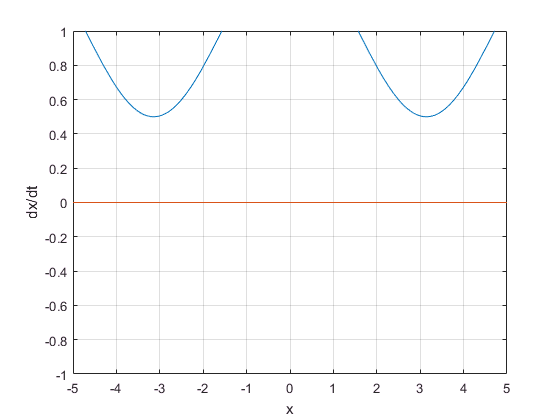

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on


% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num =    0.0000 + 0.8660i
   0.0000 - 0.8660i



% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


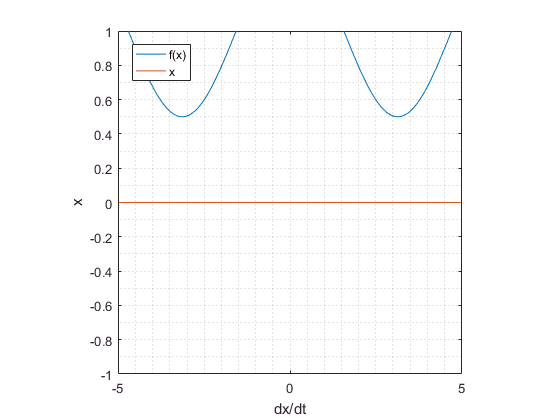

fplot(0)

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 4
syms f(x)
f(x)= sin(x)-cos(3*x);

figure
fplot(f(x))
hold

Current plot held


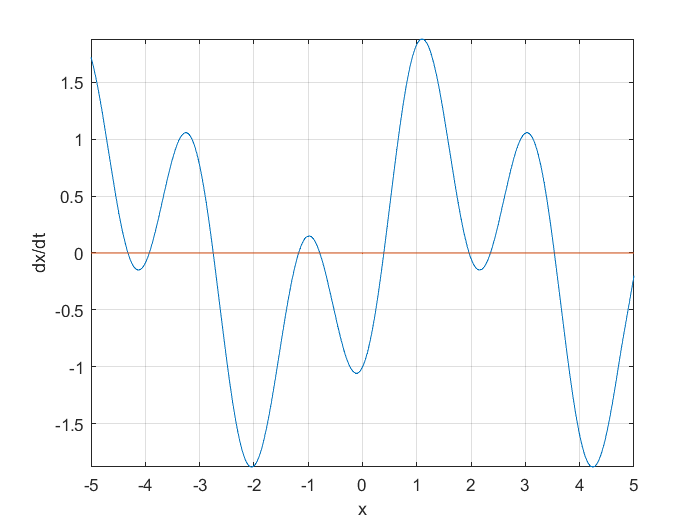

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on


% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0);

% probe other fixed points that were not identified by the solve command
% using vpasolve (help vpasolve) - for example around a value -2.5
fp = vpasolve(f(x),x,-2.5)

$$fp = -2.7488935718910690836548129603696$$


% probe other fixed points around a value -1
fp = vpasolve(f(x),x,-1)

$$fp = -1.1780972450961724644234912687298$$


% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = 1.5307


% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


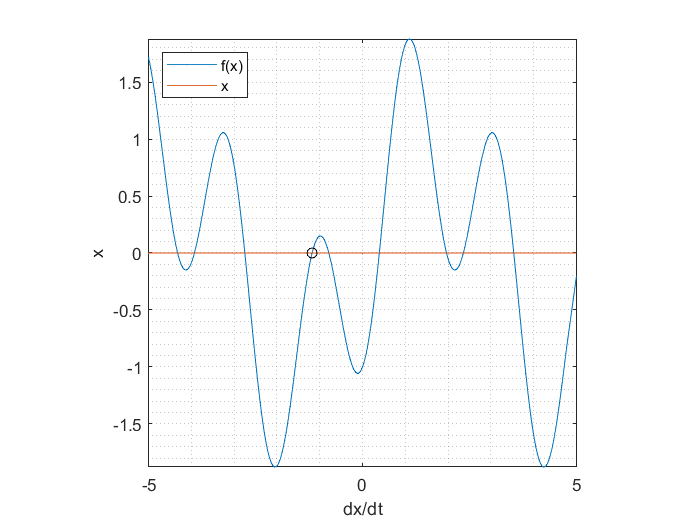

fplot(0)

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 5
syms f(x)
f(x)= exp(1)^x-2*cos(x);

figure
fplot(f(x))
hold

Current plot held


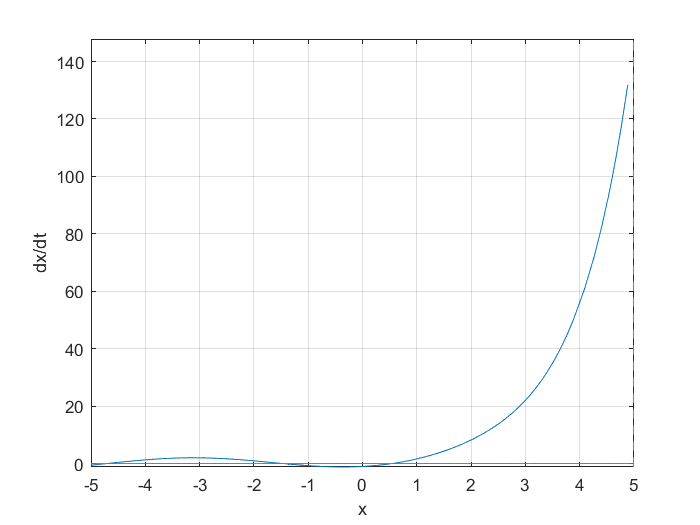

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on


% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0);


% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = 2.7435


% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


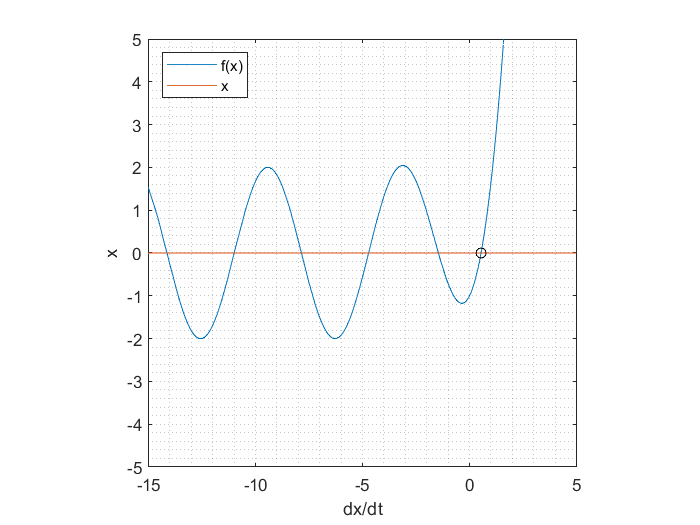

fplot(0)
ylim([-5 5])
xlim([-15 5])

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

## Part II (bonus) Write a Matlab live script for the below HKB model parameter settings and complete the following: (a) find the fixed points; (b) find that stability of fixed points; and (c) plots the below ODE function with the fixed ponts (classified by color). 

syms f(x) 
b = [1,.5,.3,1,1]

b =     1.0000    0.5000    0.3000    1.0000    1.0000


a = [2,2,2,2,2]

a =      2     2     2     2     2


d_omega = [0,0,0,.15,1]

d_omega =          0         0         0    0.1500    1.0000


f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

figure
fplot(f(x))
hold

Current plot held


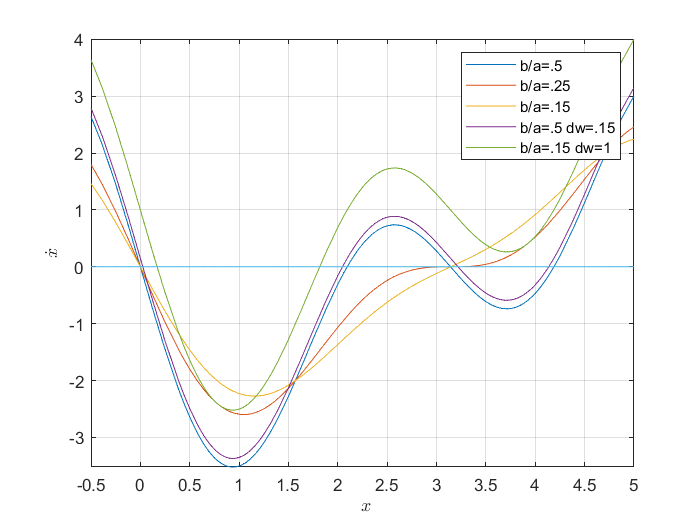

fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-0.5 5])
legend('b/a=.5','b/a=.25','b/a=.15','b/a=.5 dw=.15', 'b/a=.15 dw=1')

% Equation 1 (b/a=.5, dw=0)
syms f(x) 
b = 1

b = 1

a = 2

a = 2

d_omega = 0

d_omega = 0

f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0)

$$fp = \left(\begin{array}{c} 0\\ -\frac{2\,\pi }{3}\\ \frac{2\,\pi }{3} \end{array}\right)$$


% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num =     -6
     3
     3



% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


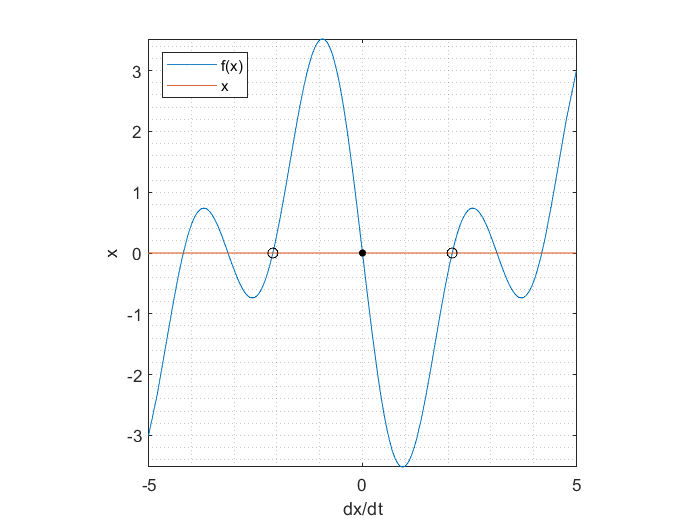

fplot(0)
xlabel('x')
ylabel('dx/dt')

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 2 (b/a=.25, dw=0)
syms f(x) 
b = .5

b = 0.5000

a = 2

a = 2

d_omega = 0

d_omega = 0

f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0)

$$fp = 0$$


% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% Since the standard symbolic solve function did not work, find the fixed
% points manually using vpa solve. Here, find the roots around the initial
% condition of 0.
fp = vpasolve(f(x)==0,x,0)

$$fp = 0$$


% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = -4


% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


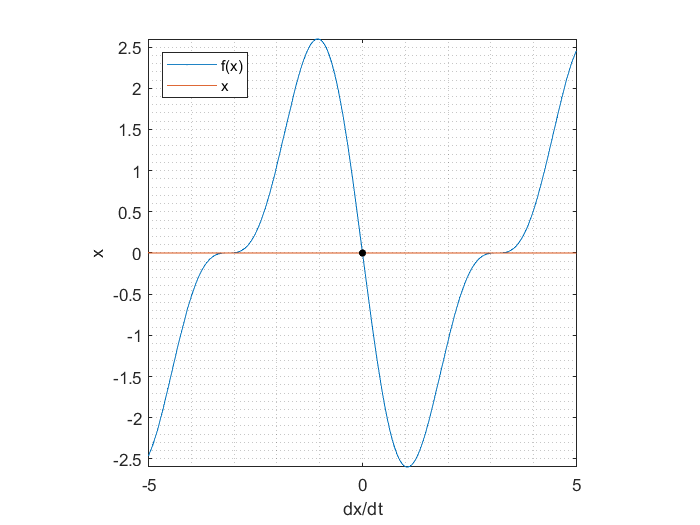

fplot(0)
xlabel('x')
ylabel('dx/dt')

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 3 (b/a=1.5, dw=0)
syms f(x) 
b = .3

b = 0.3000

a = 2

a = 2

d_omega = 0

d_omega = 0

f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0)

$$fp = \left(\begin{array}{c} 0\\ \pi +\mathrm{acos}\left(\frac{5}{3}\right)\\ \pi -\mathrm{acos}\left(\frac{5}{3}\right) \end{array}\right)$$


% Since the standard symbolic solve function did not work, find the fixed
% points manually using vpa solve. Here, find the roots around the initial
% condition of 2.
fp = vpasolve(f(x)==0,x,2)

$$fp = 3.1415926535897932384626433832795$$


% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = 0.8000


% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure

fplot(f(x))
hold

Current plot held


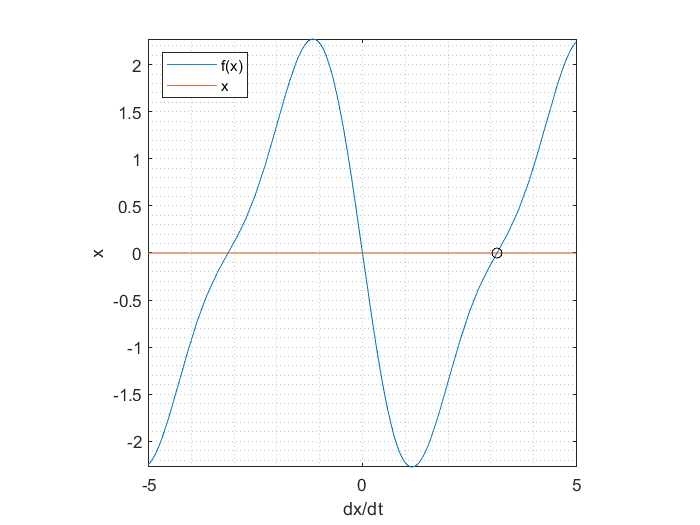

fplot(0)
xlabel('x')
ylabel('dx/dt')

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 4 (b/a=.5, dw=0.15)
syms f(x) 
b = 1

b = 1

a = 2

a = 2

d_omega = 0.15

d_omega = 0.1500

f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0)

$$fp = -\log\left(\mathrm{root}\left(z^{4}+z^{3}-\frac{3\,z^{2}\,\mathrm{i}}{20}-z-1,z,1\right)\right)\,\mathrm{i}$$


% Since the standard symbolic solve function did not work, find the fixed
% points manually using vpa solve. Here, find the roots around the initial
% condition of 0.
fp = vpasolve(f(x)==0,x,0)

$$fp = 0.02500781893601448736476066659009$$


% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = -5.9944


% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


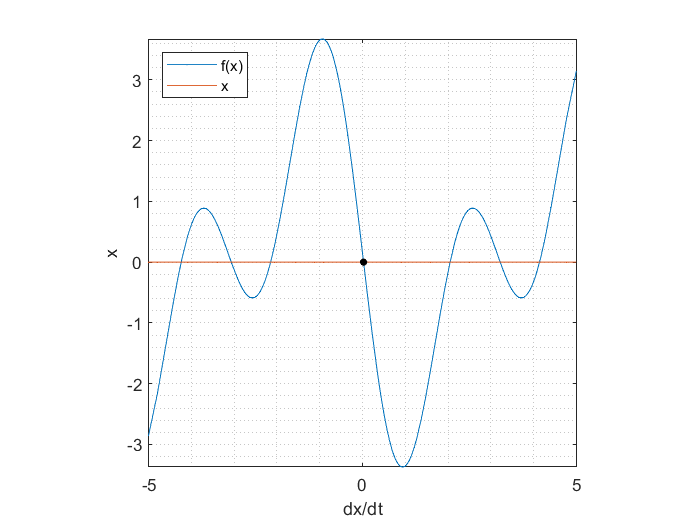

fplot(0)
xlabel('x')
ylabel('dx/dt')

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 5a (b/a=.25, dw=+1)
syms f(x) 
b = 1

b = 1

a = 2

a = 2

d_omega = 1

d_omega = 1

f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0)

$$fp = -\log\left(\mathrm{root}\left(z^{4}+z^{3}-z^{2}\,\mathrm{i}-z-1,z,1\right)\right)\,\mathrm{i}$$


% Since the standard symbolic solve function did not work, find the fixed
% points manually using vpa solve. Here, find the roots around the initial
% condition of 0.
fp = vpasolve(f(x)==0,x,0)

$$fp = 0.16907046133832688004553048956224$$



% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = -5.7450


% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


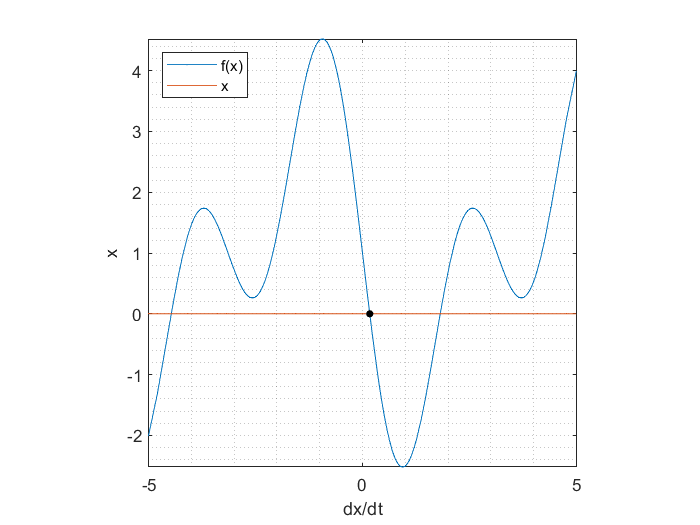

fplot(0)
xlabel('x')
ylabel('dx/dt')

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')

% Equation 5b (b/a=.25, dw=-1)
syms f(x) 
b = 1

b = 1

a = 2

a = 2

d_omega = -1

d_omega = -1

f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0)

$$fp = -\log\left(\mathrm{root}\left(z^{4}+z^{3}+z^{2}\,\mathrm{i}-z-1,z,1\right)\right)\,\mathrm{i}$$


% Since the standard symbolic solve function did not work, find the fixed
% points manually using vpa solve. Here, find the roots around the initial
% condition of 0.
fp = vpasolve(f(x)==0,x,0)

$$fp = -0.16907046133832688004553048956224$$


% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num = -5.7450


% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


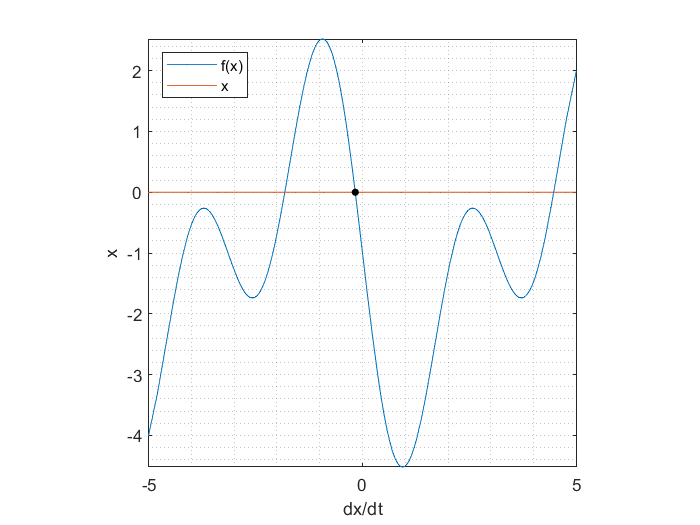

fplot(0)
xlabel('x')
ylabel('dx/dt')

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')